## 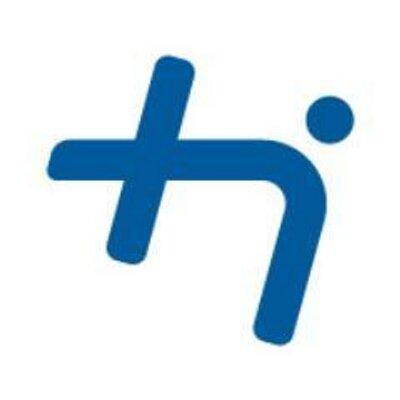**Prof. Dr. Michael Mecking **

### **Practical Course - Digital Signal Processing / AVE**   

# **The Sampling Theorem & Aliasing**

### **The Sampling Theorem**

Given that a signal $x(t)$is band-limited to a frequency range of $W$, i.e., that


$$X(f) \equiv 0 \quad \text{for} \quad |f| > W,$$


samples taken at a rate of $f_S \ge 2W$ (or correspondingly at intervals of $T_S \le 1/(2W)$) will be sufficient for a perfect reconstruction of the original signal by the interpolation / reconstruction formula


$$x(t) =\sum_{n=-\infty}^{\infty} x(nT_S) \, \frac{ \sin\left( \pi/T_S (t - nT_S)\right) }{\pi/T_S (t - nT_S)}.$$


## **Reconstruction / Digital to Analogue Conversion**

### **Problem 1.1**

Please download the file *bowie.mat* from Moodle and import the file (or the two xariables $x$ and $f_s$) into your workspace. This time, the audio file is audible without interferer ;-)

The samples are taken from a file in **wav-format. **It is a lossless format to store sounds on a hard drive (actually, it is/was used for the CD-standard). Each audio sample is quantised to 16 bit and represented by a floating point value in the range from -1 to 1. Samples are taken at a sampling frequency of $f_S = 44.100$ Hz. All our sound files are mono or single channel.

Reconstruct the continuous-time signal $x(t)$ from the samples $x[n]$ in the wav-file using the *sound* command from MATLAB with the appropriate sampling frequency $f_S$. 

% load the discrete-time samples and reconstruct the continuous-time Bowie-audio file 

% your code...
load('bowie.mat')
sound(x,fs)

### Problem 1.2

Without changing the discrete-time samples $x[n]$ reconstruct the continuous-time audio-signal $x(t)$ using a different (assumed) sampling frequencies in the *sound* command:

-  $f_{S,1}$ which is just one half of the original sampling frequency: $f_{S,1} = \frac12 \ f_S$

- $f_{S,2}$ which is twice as high as the original: $f_{S,2} = 2\,f_S$

% reconstruct the audio file using different sampling frequencies
% your code...
fs_1=0.5*fs

fs_1 = 22050

sound(x,fs_1)
%fs_2=2*fs
%sound(x,fs_2)

**What do you notice? **

- when we play fs_1 then the speed of the track in get slower to 0.5x. Because we have decrees the frequence to 0.5

- and when we multiply the frequence it will get faster 

## Chirp Signal

### Problem 2.1

Generate a **chirp-signal **$x(t)$, i.e., a sine-signal with a linearly increasing frequency $f(t)$:

$x(t) = \sin \left( 2\pi \, f(t) \cdot t \right)$.

The signal should be sampled with a frequency $f_S = 2$ kHz and have a duration of 3 seconds. After 1 second the chirp should have a frequency of 261.63 Hz correspoding to the musical note $C_4$.

The MATLAB command *chirp* will prove to be very useful here. Check your MATLAB documentation.

% chirp signal
% your code...
fs=2000

fs = 2000

t=0:1/fs:3;
y=chirp(t,0,1,261.63)

y =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9994    0.9992    0.9989    0.9986    0.9982    0.9978    0.9972    0.9966    0.9959    0.9951    0.9941    0.9930    0.9918    0.9904    0.9888    0.9871    0.9851    0.9829    0.9806    0.9779    0.9751    0.9719    0.9685    0.9647    0.9607    0.9563    0.9516    0.9464    0.9409    0.9350    0.9287    0.9219    0.9147    0.9070    0.8987    0.8900    0.8807


### Problem 2.2Reconstruct and listen to the continuous-time chirp signal $x(t)$.

% your code...
sound(y,fs)

### Problem 2.3

What follows is a view of the chirp-signal in a time-frequency plane (we will not discuss these in class and they are not relevant for the final exam!). The continuous time-signal $x(t)$ is cut into small non-overlapping pieces, which are separately analysed in frequency using the (discrete-time) Fourier-Transform. This provides us with a "blurry" picture of the chirp you just created. You should be able to see an "energy-distribution" in the time-frequency-plane which resembles what you have just heard.

By following this approach, one is able to resolve the different frequencies over time at the expense of a "smearing" of the content in the frequency-domain. One cannot exactly tell at which time a certain frequency is present. This is called **time-bandwidth uncertainty **because it is similiar to the Heisenberg's uncertainty principle in quantum mechanics. 

In order to measure a change in the signal and analyse the rate of change (i.e., frequency) an observation of the signal over a small period of time is necessary. This prevents assigning both a certain time and a certain frequency content.

Just give it a try...

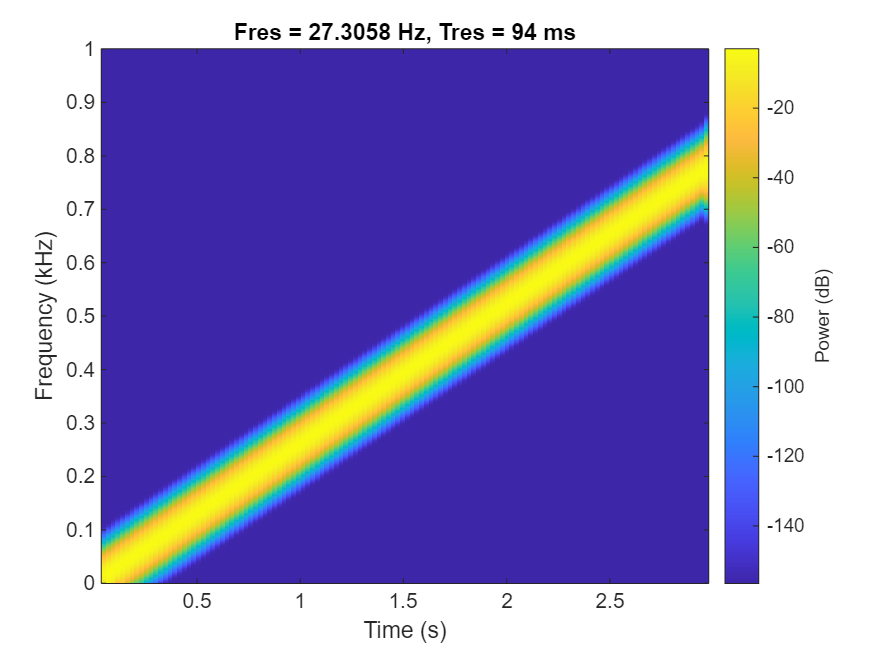

% Plot the spectrogram of the signal x sampled with a sampling frequency fs
% replace in case with own variables...

pspectrum(y, fs,'spectrogram','FrequencyLimits',[0, fs/2]);

### Problem 2.4

Redo the exercise but extend your chirp signal to last 7.7 seconds - otherwise don't change anything.

% extend the duration of the chirp and redo exercise before
% your code...
fs=2000

fs = 2000

t=0:1/fs:7.7;
y=chirp(t,0,1,261.63)

y =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9994    0.9992    0.9989    0.9986    0.9982    0.9978    0.9972    0.9966    0.9959    0.9951    0.9941    0.9930    0.9918    0.9904    0.9888    0.9871    0.9851    0.9829    0.9806    0.9779    0.9751    0.9719    0.9685    0.9647    0.9607    0.9563    0.9516    0.9464    0.9409    0.9350    0.9287    0.9219    0.9147    0.9070    0.8987    0.8900    0.8807


### Problem 2.5

Reconstruct and listen to your extended chirp signal $x(t)$.

% reconstruct the extended chirp signal based on the samples
% your code...
sound(y,fs)

**What do you notice? Can you explain what's happening?**

### Problem 2.6

You might want to look yet again at the time-frequency analysis of the signal to verify your thoughts:

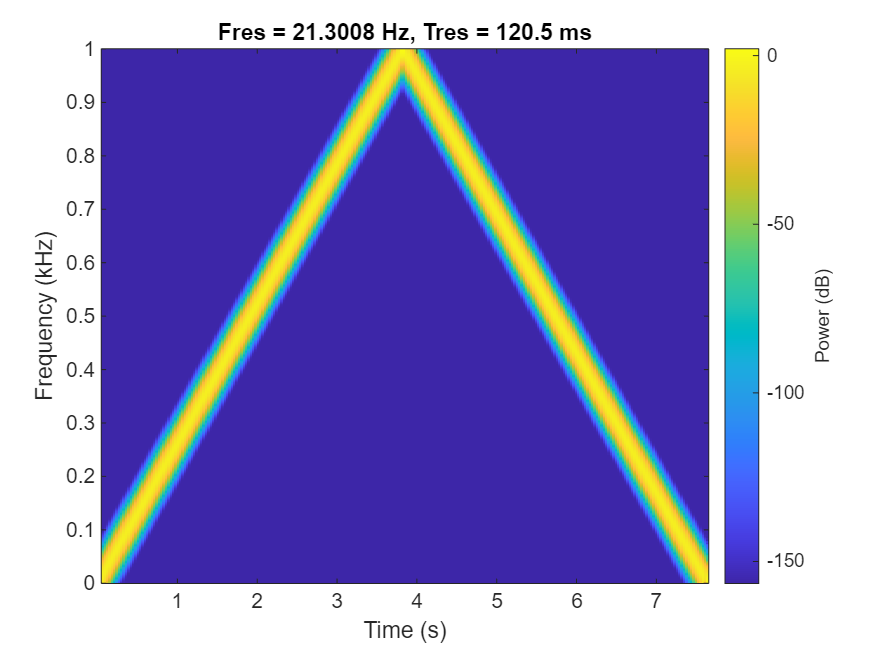

% Plot the spectrogram of the signal x sampled with sampling frequency fs
% replace in case with own variables...

pspectrum(y, fs, 'spectrogram', 'FrequencyLimits',[0, fs/2]);

### **Problem 2.7**

What do you need to change in generating / sampling the chirp-signal in order to be able to produce the original audio signal which contains the intended chirp with instantaneous frequency linearly increasing for the whole interval of 7.7 seconds? 

Modify appropriately and reconstruct and listen to the chirp.

% modified signal generation / sampling - including reconstruction
% your code...
fs=4000

fs = 4000

t=0:1/fs:7.7;
y=chirp(t,0,1,261.63)

y =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9997    0.9996    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9982    0.9980    0.9978    0.9975    0.9972    0.9969    0.9966    0.9963    0.9959    0.9955    0.9951    0.9946    0.9941    0.9936    0.9930    0.9924


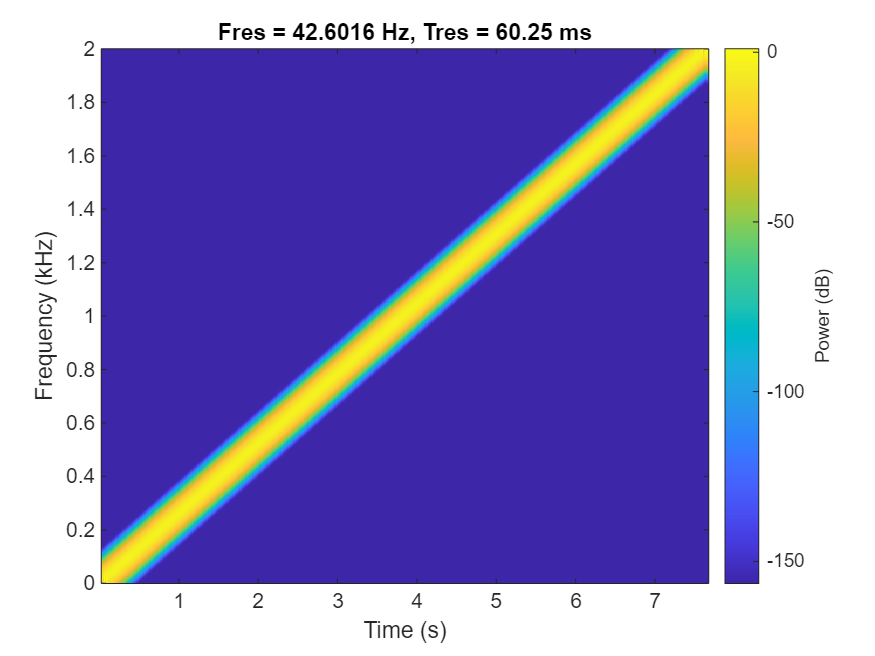

sound (y,fs)
pspectrum(y, fs, 'spectrogram', 'FrequencyLimits',[0, fs/2]);

## Downsampling and Anti-Aliasing Filter

We will work with a signal $x(t)$ consisting of three consecutive sine-waveforms of frequencies $f_1 = 250$, $f_2 = 500$, and $f_3 = 1600$ Hz, respectively. 

Each sine-waveform has a duration of one second, so that the overall signal has a duration of three seconds. 

### **Problem 3.1**

What is the minimum value for the sampling frequency $f_S$ if you want to be able to ideally reconstruct the signal $x(t)$?

**Answer: 2*f_3**

### **Problem 3.2**

The following code realises the signal $x[n]$ as a sampled version of the continuous-time signal $x(t)$.

% generate the sine-signals with frequencies 250, 500, and 1600 Hz, respectively. 
% The sampling frequency is chosen to be fs = 4000 Hz.
fs = 4000;
f = [250 500 1600];

% samples of each sine will be taken for a second, i.e., fs samples each.
x = [];
n = 1 : 1 : fs;

for k = 1 : 3
    % take a second of each sine signal using frequency f(k)
    x_new = sin( 2*pi * f(k)/fs * n );

    % append new signal to previous signals
    x = [x x_new];
end

Reconstruct the sine-waves $x(t)$ using the samples $x[n]$ and listen to the audio signal.

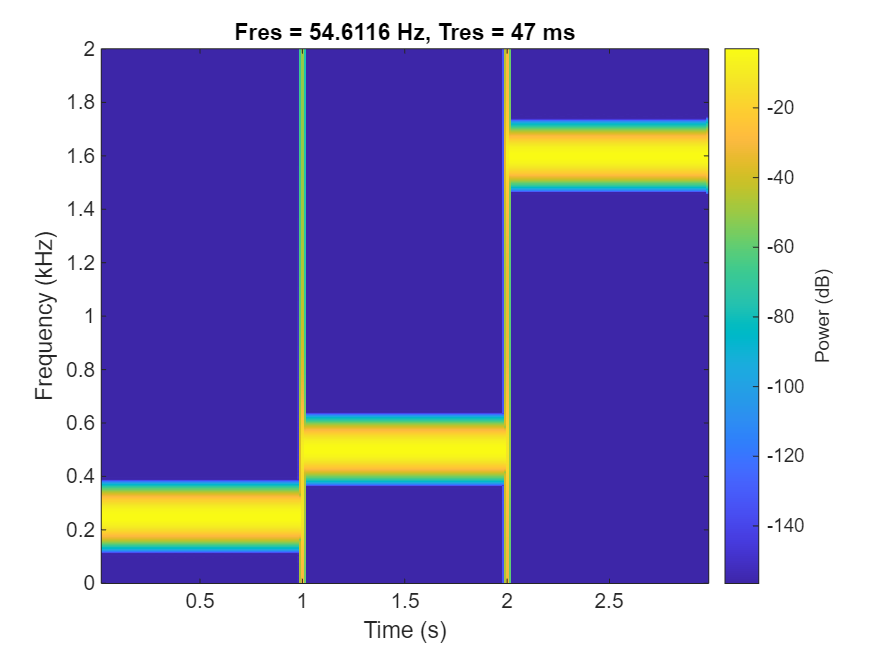

% Reconstruction of the signal x(t)
sound(x, fs)
pspectrum(x, fs, 'spectrogram', 'FrequencyLimits',[0, fs/2]);

### Problem 3.3

Assume you are actually only interested in the two sine-waves having the lower frequencies of $f_1=250$ and $f_2=500$ Hz. Ignoring the sine-wave at $f_3 = 1600$ Hz, you could have sampled the signal at a sampling frequency of merely $f_{S,2}=2000$ Hz.

Which samples of your discrete-time signal $x[n]$ would you have obtained if you had sampled at one half of the sampling rate, i.e., at rate $f_{S,2}$ instead of the larger $f_S = 2 \, f_{S,2}$?

This process is called **downsampling** by a factor of $2$. 

Implement this downsampling procedure and create a signal $x_2[n]$ which comprises the samples of the original signal $x(t)$ taken at half the sampling rate.

% downsampling by a factor of 2
% your code...
fs = 4000;
f = [250 500 1600];

% samples of each sine will be taken for a second, i.e., fs samples each.
x = [];
n = 1 : 1 : fs;

for k = 1 : 3
    % take a second of each sine signal using frequency f(k)
    x_new = sin( 2*pi * f(k)/fs * n );

    % append new signal to previous signals
    x = [x x_new];
end

y= downsample(x,2)

y =     0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239


x_2 =     0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239


sound(y,fs/2)

### Problem 3.4

Reconstruct the original signal using the samples $x_2[n]$. Mind to properly adjust the sampling rate for reconstruction!

**Observations: What has happened?**

### Problem 3.5

How could you prevent the alias to occur if you were - as described - only interested in the two sines of lower frequency and hence, operate with a lower sampling frequency?

**Answer: ** 

Create the lowpass anti-aliasing filter and downsample the resulting signal by a factor of 2. 

Listen to the file you created!

% Create a lowpass filter (to be covered in the lecture later this semester!) and 
% filter the original signal to eliminate any frequency larger than W = 1000 Hz. 
% Hence, this signal can be downsampled to half the rate (fs = 2000 instead of 4000 Hz) 
% without any further distortion due to aliasing!

% you may use a standard low-pass filter provided by MATLAB:
% "output" = lowpass("input", "cutoff frequency in multiples of pi")

% your code...
y= downsample(x,2)

y =     0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239


fs = 4000;
f = [250 500 1600];

% samples of each sine will be taken for a second, i.e., fs samples each.
x = [];
n = 1 : 1 : fs;

for k = 1 : 3
    % take a second of each sine signal using frequency f(k)
    x_new = sin( 2*pi * f(k)/fs * n );

    % append new signal to previous signals
    x = [x x_new];
end
x_f= lowpass(x,1000,fs);
x_y=x_f(1:2:end)

x_y =     0.3468    0.9410    0.9141    0.3884   -0.3859   -0.9224   -0.9241   -0.3832    0.3837    0.9227    0.9252    0.3815   -0.3816   -0.9247   -0.9232   -0.3832    0.3830    0.9237    0.9240    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239    0.9239    0.3827   -0.3827   -0.9239   -0.9239   -0.3827    0.3827    0.9239


sound (x_f,fs)